% IC sound P7 
defaultDir = 'F:\Calvin\tmem16a\widefield IC sound'

defaultDir = 'F:\Calvin\tmem16a\widefield IC sound'

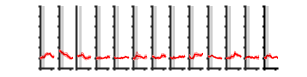

cd(defaultDir);

% load files
addpath('467_1 tecta flfl P8 sound stim','467_3 tecta flfl P8 sound stim','489_2 tecta flfl P6 sound stim','467_2 flfl P8 sound stim');

cko1 = load('467_1_0dB.mat'); % R ear
cko2 = load('467_3_0dB.mat'); % R ear
cko3 = load('489_2_0dB.mat'); % L ear

con1 = load('467_2_0dB.mat'); % R ear

time = [1:1:length(cko1.avgRIC)];

for i = 1:16
    avgcko0db(i,:) = nanmean([cko1.avgLIC(i,:);cko2.avgLIC(i,:);cko3.avgRIC(i,:)],1);
    stdcko0db(i,:) = nanstd([cko1.avgLIC(i,:);cko2.avgLIC(i,:);cko3.avgRIC(i,:)],1)/sqrt(3);
end

% average - 3 animals
figure
for i = 1:13
    subplot(1,13,i);
    c1 = shadedErrorBar(time,avgcko0db(i,:)-min(avgcko0db(i,:))+0.05,stdcko0db(i,:),'lineprops','r');
    c1.mainLine.LineWidth = 1;
    hold on
    ylim([0 0.30])
    yticklabels([]);
    xticklabels([]);
    patch([10 10 20 20], [1 -6 -6 1],'k','EdgeColor','none','FaceAlpha',0.2);
end
figQuality(gcf,gca,[3.2 0.8])

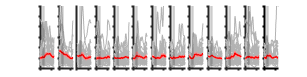


% mean with individual traces
l_grey = [0.7 0.7 0.7];
figure
for i = 1:13
    subplot(1,13,i);
    hold on
    for j = 1:10
        plot(cko1.RICsig(j,:,i),'Color',l_grey,'LineWidth',0.25)
        plot(cko2.RICsig(j,:,i),'Color',l_grey,'LineWidth',0.25)
        plot(cko3.LICsig(j,:,i),'Color',l_grey,'LineWidth',0.25)
    end
      c1 = shadedErrorBar(time,avgcko0db(i,:)-min(avgcko0db(i,:))+0.05,stdcko0db(i,:),'lineprops','r');
    c1.mainLine.LineWidth = 1;
    ylim([0 0.30])
    yticklabels([]);
    xticklabels([]);
    patch([10 10 20 20], [1 -6 -6 1],'k','EdgeColor','none','FaceAlpha',0.2);
end
figQuality(gcf,gca,[3.2 0.8])

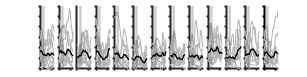


% con example - just 1
l_grey = [0.7 0.7 0.7];
figure
for i = 1:13
    subplot(1,13,i);
    hold on
    for j = 1:10
        plot(con1.LICsig(j,:,i),'Color',l_grey,'LineWidth',0.25)
    end
     % c1 = shadedErrorBar(time,avgcko0db(i,:)-min(avgcko0db(i,:))+0.05,stdcko0db(i,:),'lineprops','r');
   % c1.mainLine.LineWidth = 1;
   plot(time,[con1.avgLIC(i,:)],'k','LineWidth',1)
    ylim([0 0.30])
    yticklabels([]);
    xticklabels([]);
    patch([10 10 20 20], [1 -6 -6 1],'k','EdgeColor','none','FaceAlpha',0.2);
end
figQuality(gcf,gca,[3.2 0.8])